[y,Fs]=audioread("C:\Users\TEJAS V\Downloads\ado2.wav");
save press y Fs

filename = 'testaudio2.unknown.wav';%pp.wav
audiowrite(filename,y,Fs);
clear y Fs 
[y,Fs] = audioread(filename);

%IIR
bsFilt = designfilt('bandstopiir','FilterOrder',60,'HalfPowerFrequency1',50,'HalfPowerFrequency2',200,'SampleRate',8000);

dataIn = y,Fs;

dataIn =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


dataOut = filter(bsFilt,dataIn);

%FIR
bsFilt = designfilt('bandstopfir','FilterOrder',200,'CutoffFrequency1',50,'CutoffFrequency2',200,'SampleRate',8000);

dataIn = y,Fs;

dataIn =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


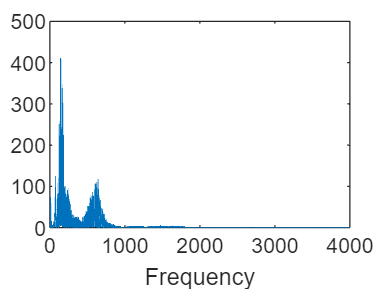

dataOut2 = filter(bsFilt,dataIn);


%Playing audio
sound(y,Fs)   %Input audio
pause(10)
sound(dataOut,Fs)    %IIR audio
pause(10)
sound(dataOut2,Fs)   %FIR audio

fs = 8000;
nfft = 419146;
f = linspace(0,fs,nfft);
Y = abs(fft(y,nfft));

figure;
plot(f(1:nfft/2), Y(1:nfft/2));
xlabel('Frequency')

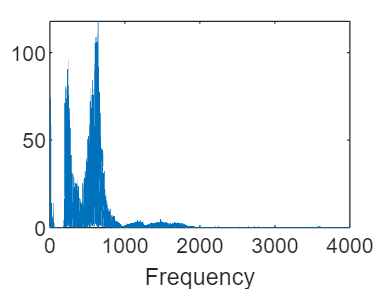



nfft = 419146;
f = linspace(0,fs,nfft);
Y = abs(fft(dataOut,nfft));

figure;
plot(f(1:nfft/2), Y(1:nfft/2));
xlabel('Frequency')

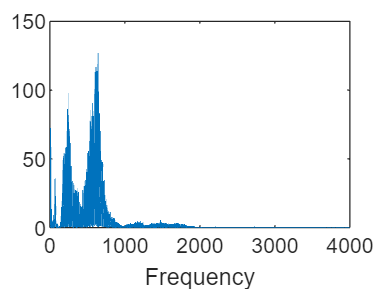


nfft = 419146;
f = linspace(0,fs,nfft);
Y = abs(fft(dataOut2,nfft));

figure;
plot(f(1:nfft/2), Y(1:nfft/2));
xlabel('Frequency')